# Photodiode Model 

Copyright (C) 2021 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

************ Modify to work with the non-ideal diode in the file PhotoDetectorModel1.slx

## Introduction

This notebook provides an introduction to a photodetector model with parameters obtained from online photodiode datasheets. The model is to be compared with the photodiode block that already exists in Simscape and have its output current be plotted against incident light power. 

Photodiodes convert light energy to current which is generated when light is incident on the device. The Light-Emitting Diodes (LED) converts current to light energy. Diodes are semiconductor devices which basically act as a switch in an electrical circuit. They can be connected in forward-bias in an electrical circuit to allow current to flow through it, or in a reverse-bias connection to prevent current from flowing through it.

Simscape provides a photodiode block however, our goal will be to be modelled it as an equivalent circuit that includes current source connected in parallel with junction capacitance, shunt and load resistances. 

## Simscape Photodiode Block

The following simple model was created on simscape using the photodiode block: 

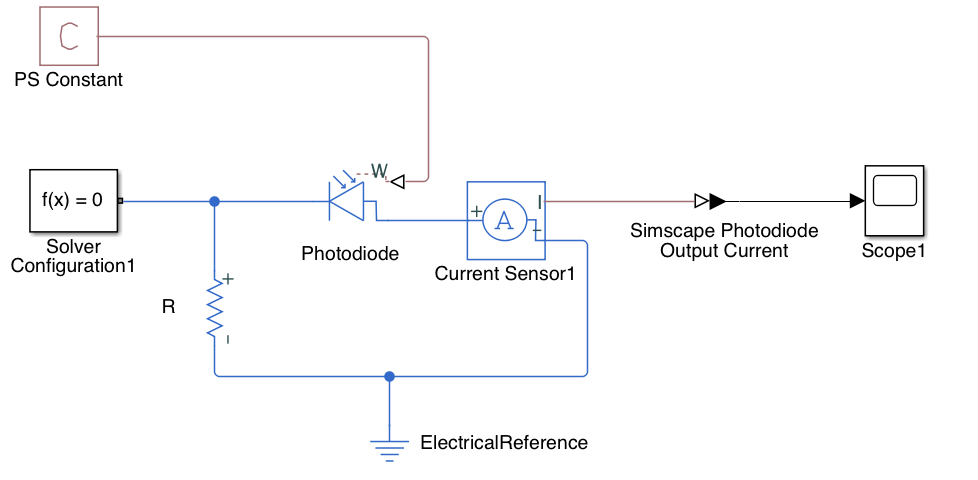

The parameters and chosen values for this circuit include: 

- photodiode current: I_p = 0.000052 A

- current 1:  I_1 = 0.1 A 

- voltage 1: V_1 = 1.3 V 

- dark current: I_d = 0.1 nA 

- ohmic resistance: R_s = 0.1 Ω 

- measurement temperature: T = 23 oC 

- junction capacitance: C = 1.8 pF 

- total series resistance: R = 60 Ω 

These values will be set into the simscape model:

model_name = 'PhotodetectorModel';
open_system(model_name);
sim(model_name)

ans =   Simulink.SimulationOutput:

           current1_out: [1x1 timeseries] 
           current2_out: [1x1 timeseries] 
                   tout: [98x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



set_param('PhotodetectorModel/Photodiode1','G','0.00013')
set_param('PhotodetectorModel/Photodiode1','I2','0.1')
set_param('PhotodetectorModel/Photodiode1','V2','1.3')
set_param('PhotodetectorModel/Photodiode1','IS','0.1')
set_param('PhotodetectorModel/Photodiode1','RS','0.1')
set_param('PhotodetectorModel/Photodiode1','Tmeas','23')
set_param('PhotodetectorModel/R','R','60')

Most of the electrical parameters came from the datasheet of First Sensor’s PS0.25-5 High Speed NIR-sensitive PIN Photodiode [1]. Values from Vishay’s BPV10NF Silicon Pin Diode [2] and photodiode application notes from OSI Electronics [3] were also considered. Parameters that were in the Simscape photodiode, but not the photodiode model, were kept at their default values.

It is important to note that the Simscape photodiode has an input of radiant flux intensity. The first sensor diode has an active radiant area (A) of 0.25 mm2[1], so for an incident light power of 1 W, the radiant flux intensity is as follows:

Intensity=  P/A=(0.001 W)/(0.25 〖mm)]^2 )=  0.0004  W/〖mm)]^2

Therefore, the photodiode current is the following:

I_p=A×R(λ)×Intensity=(0.25 〖mm)]^2 )(0.52 A/W)(0.0004 W/〖mm)]^2 )= 0.000052 A

The output current is measured using a current sensor included in the circuit. The following output plot can be observed as an output current as a function of time for a constant incident light power of 1 mW and a simulation time of 0.5 s . 

simOut = sim('PhotodetectorModel', 'CaptureErrors', 'on');
figure
a1=plot(simOut.current1_out.Time,simOut.current1_out.Data, 'b')

a1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×98 double]
              YData: [1×98 double]
              ZData: [1×0 double]

  Show all properties


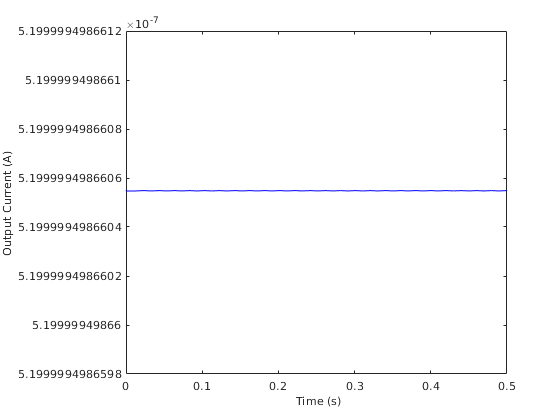

xlabel(' Time (s)', 'FontSize', 10)
ylabel('Output Current (A)', 'FontSize', 10)

## Simscape Photodiode Model

The following model was created on simscape with parameters obtained from online photodiode datasheets. This model is to be compared with the photodiode block that already exists in Simscape. 

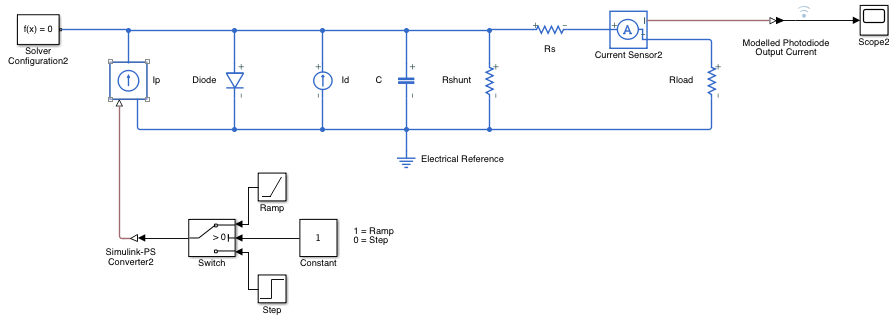

The parameters and chosen values for this circuit include: 

- photodiode current: I_p = 0.00000052 A 

- forward voltage: V_f = 1.3 V 

- dark current: I_d = 0.1 nA 

- junction capacitance: C = 1.8 pF 

- shunt resistance: R_shunt = 1000 MΩ 

- series resistance: R_s = 10 Ω 

- load resistance: R_load = 50 Ω 

set_param('PhotodetectorModel/Step','After','0.00000052')
set_param('PhotodetectorModel/Diode','Vf','1.3')
set_param('PhotodetectorModel/Id','dc_current','0.1')
set_param('PhotodetectorModel/C','c','1.8')
set_param('PhotodetectorModel/Rshunt','R','1000')
set_param('PhotodetectorModel/Rs','R','10')
set_param('PhotodetectorModel/Rload','R','50')

The output current is measured using a current sensor included in the circuit. The following output plot can be observed as an output current as a function of time for a constant incident light power of 1 mW and a simulation time of 0.5 s .

simOut = sim('PhotodetectorModel', 'CaptureErrors', 'on');
figure
a2=plot(simOut.current2_out.Time,simOut.current2_out.Data,'r')

a2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×73 double]
              YData: [1×73 double]
              ZData: [1×0 double]

  Show all properties


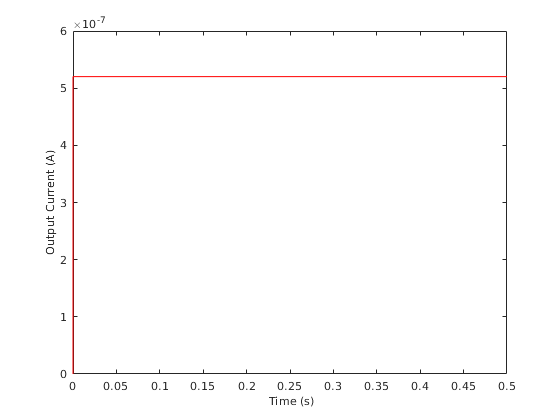

xlabel(' Time (s)', 'FontSize', 10)
ylabel('Output Current (A)', 'FontSize', 10)

## Comparing Circuits 

Parameters in common are photodiode current, dark current, junction capacitance, series resistance and load resistance. The modelled photodiode uses a forward voltage for an ordinary diode, whereas the Simscape photodiode uses an I-V characteristic datapoint. Furthermore, shunt resistance is a parameter that is included in the modelled photodiode, but not the Simscape photodiode.

The following plot can be seen which includes both the output currents as a function of time for a constant incident light power of 1 mW and a simulation time of 0.5 s 

simOut = sim('PhotodetectorModel', 'CaptureErrors', 'on');
figure
a3=plot(simOut.current1_out.Time,simOut.current1_out.Data, 'b', simOut.current2_out.Time,simOut.current2_out.Data,'r')

a3 =   2×1 Line array:

  Line
  Line


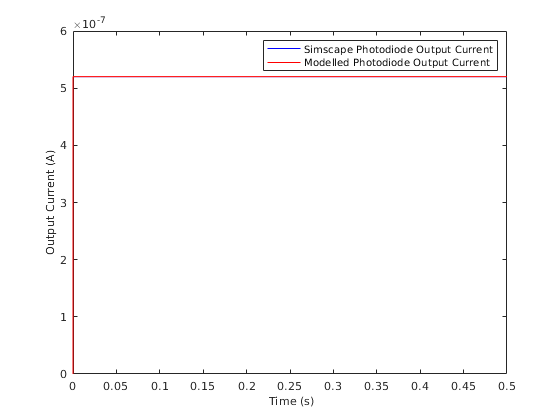

n1 = "Simscape Photodiode Output Current";
n2 = "Modelled Photodiode Output Current";
legend([a3], [n1, n2]);
xlabel(' Time (s)', 'FontSize', 10)
ylabel('Output Current (A)', 'FontSize', 10)

The output current for the Simscape photodiode is 0.52 µA  and the output current for the modelled photodiode is 0.5201 µA  for the initial chosen parameters. Since these currents are approximately equal, the existing Simscape photodiode is an adequate representation of the modelled photodiode.

## **Exercise **

Evaluate how changing the values will affect the photodiode sensor.

We will consider new parameters for the modelled circuit which will come from the datasheet of First Sensor’s PS1.0-5 High Speed NIR-sensitive PIN Photodiode [1]. Some parameters that were missing from this datasheet were assumed to be values coming from Vishay’s BPV10NF Silicon Pin Diode [2] and photodiode application notes from OSI Electronics [3]. 

This sensor diode has an active radiant area (A) of 1 mm^2[1], so for an incident light power of 1 mW, the radiant flux intensity is as follows:

Intensity=  P/A=(0.001 W)/(1 〖mm)]^2 )= 0.001  W/〖mm)]^2

Therefore, the photodiode current is the following:

I_p=A×R(λ)×Intensity=(0.25 〖mm)]^2 )(0.52 A/W)(1 W/〖mm)]^2 )= 0.00013A

The parameters and chosen values for the simscape photodiode circuit are: 

- photodiode current: I_p = 0.13 A 

- forward voltage: V_f = 1.3 V 

- dark current: I_d = 0.2 nA 

- junction capacitance: C = 3.5 pF 

- shunt resistance: R_shunt = 500 MΩ 

- series resistance: R_s = 10 Ω 

- load resistance: R_load = 50 Ω 

set_param('PhotodetectorModel/Step','After','0.00013')
set_param('PhotodetectorModel/Diode','Vf','1.3')
set_param('PhotodetectorModel/Id','dc_current','0.2')
set_param('PhotodetectorModel/C','c','3.5')
set_param('PhotodetectorModel/Rshunt','R','500')

The parameters and chosen values for the simscape photodiode circuit are: 

- photodiode current: I_p = 0.52 A 

- current 1:  I_1 = 0.1 A 

- voltage 1: V_1 = 1.3 V 

- dark current: I_d = 0.2 nA 

- ohmic resistance: R_s = 0.1 Ω 

- measurement temperature: T = 23 oC 

- junction capacitance: C = 1.8 pF 

- total series resistance: R = 60 Ω 

set_param('PhotodetectorModel/Photodiode1','G','0.52')
set_param('PhotodetectorModel/Photodiode1','I2','0.1')
set_param('PhotodetectorModel/Photodiode1','V2','1.3')
set_param('PhotodetectorModel/Photodiode1','IS','0.2')
set_param('PhotodetectorModel/Photodiode1','RS','0.1')
set_param('PhotodetectorModel/Photodiode1','Tmeas','23')
set_param('PhotodetectorModel/R','R','60')


The following plot can be seen which includes both the output currents as a function of time for a constant incident light power of 1 mW and a simulation time of 0.5 s 

simOut = sim('PhotodetectorModel', 'CaptureErrors', 'on');
figure
a3=plot(simOut.current1_out.Time,simOut.current1_out.Data, 'b', simOut.current2_out.Time,simOut.current2_out.Data,'r')

a3 =   2×1 Line array:

  Line
  Line


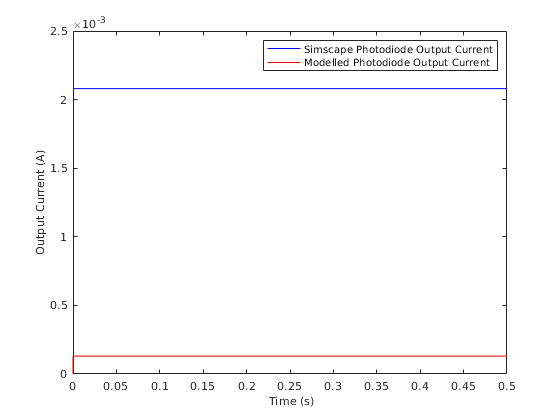

n1 = "Simscape Photodiode Output Current";
n2 = "Modelled Photodiode Output Current";
legend([a3], [n1, n2]);

xlabel(' Time (s)', 'FontSize', 10)
ylabel('Output Current (A)', 'FontSize', 10)

## References

[1]       “High speed NIR-sensitive PIN photodiodes | First Sensor.” [Online]. Available: https://www.first-sensor.com/en/products/optical-sensors/detectors/pin-photodiodes/series-5-high-speed-nir-sensitive-photodiodes/index.html. 

[2]       “BPV10NF Silicon PIN Photodiode | Vishay.” [Online]. Available: http://www.vishay.com/photo-detectors/list/product-81503/. 

[3]       “Application Notes | OSI Optoelectronics.” [Online]. Available: http://www.osioptoelectronics.com/technology-corner/application-notes.aspx. 